# **Amar Ramdas - 4461487**

## **Exercise 1:**

**P7.1. Write a program that illustrates the timescale invariance of the asset model, in the style of Figure 7.5**

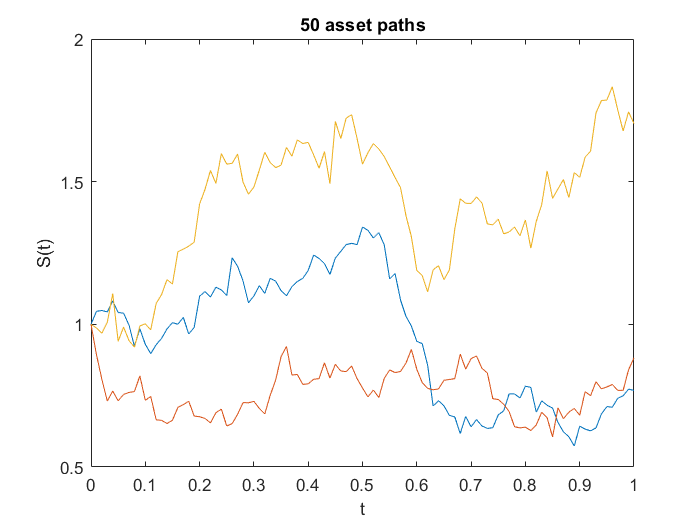

%CH07 Program for Chapter 7 % % Plot discrete sample paths
randn('state',100) ;
clf

%%%%%%%%% Problem parameters %%%%%%%%%%
S=1; mu=0.05; sigma = 0.5; L = 1e2; 
T = 1; dt =T/L; M = 3; 
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

tvals = [0:dt:T]; 
Svals = S*cumprod(exp((mu-0.5*sigma^2)*dt + sigma*sqrt(dt)*randn(M,L)),2); 
Svals = [S*ones(M,1) Svals]; % add initial asset price 
plot(tvals,Svals) 
title('50 asset paths') 
xlabel('t'), ylabel('S(t)')